clc
clear
close all 

Posición inicial

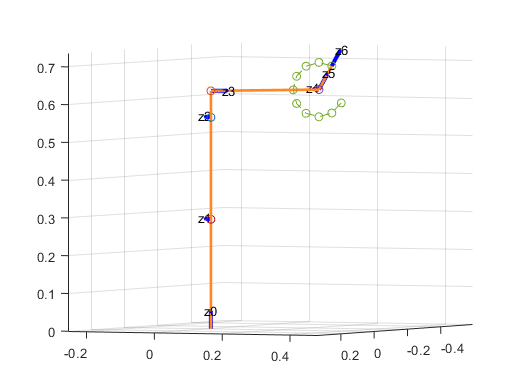

theta1=135;
theta2=-90;
theta3=-180;
theta4=0;
theta5=0;
theta6=0;
% Vectores de trayectoria de articulaciones
[H_A01,H_A02,H_A03,H_A04,H_A05,H_A06] = initTrajectory();
if false
    forcePopupFigure()
end
for i = 1:10
    w01=0;
    w12=0;
    w23=0;
    w34=0;
    w45=30;
    w56=0;
    theta1 = theta1+w01;
    theta2 = theta2+w12;
    theta3 = theta3+w23;
    theta4 = theta4+w34;
    theta5 = theta5+w45;
    theta6 = theta6+w56;
    [A01,A02,A03,A04,A05,A06] = plotRobot(theta1,theta2,theta3,theta4,theta5,theta6,false);
    [H_A01,H_A02,H_A03,H_A04,H_A05,H_A06] = saveTrajectory(A01,A02,A03,A04,A05,A06,H_A01,H_A02,H_A03,H_A04,H_A05,H_A06);

end